# derive_equations.m

Description: Symbolically derive equations related to the skateboarding robot, including the full nonlinear state-space dynamics and the state-space dynamics of the system linearized about the unstable upright equilibrium.

Inputs: none

Outputs: none

clear;
close all;
clc;

fprintf('Deriving skateboarding robot equations...\n');

Deriving skateboarding robot equations...


## Define generalized variables

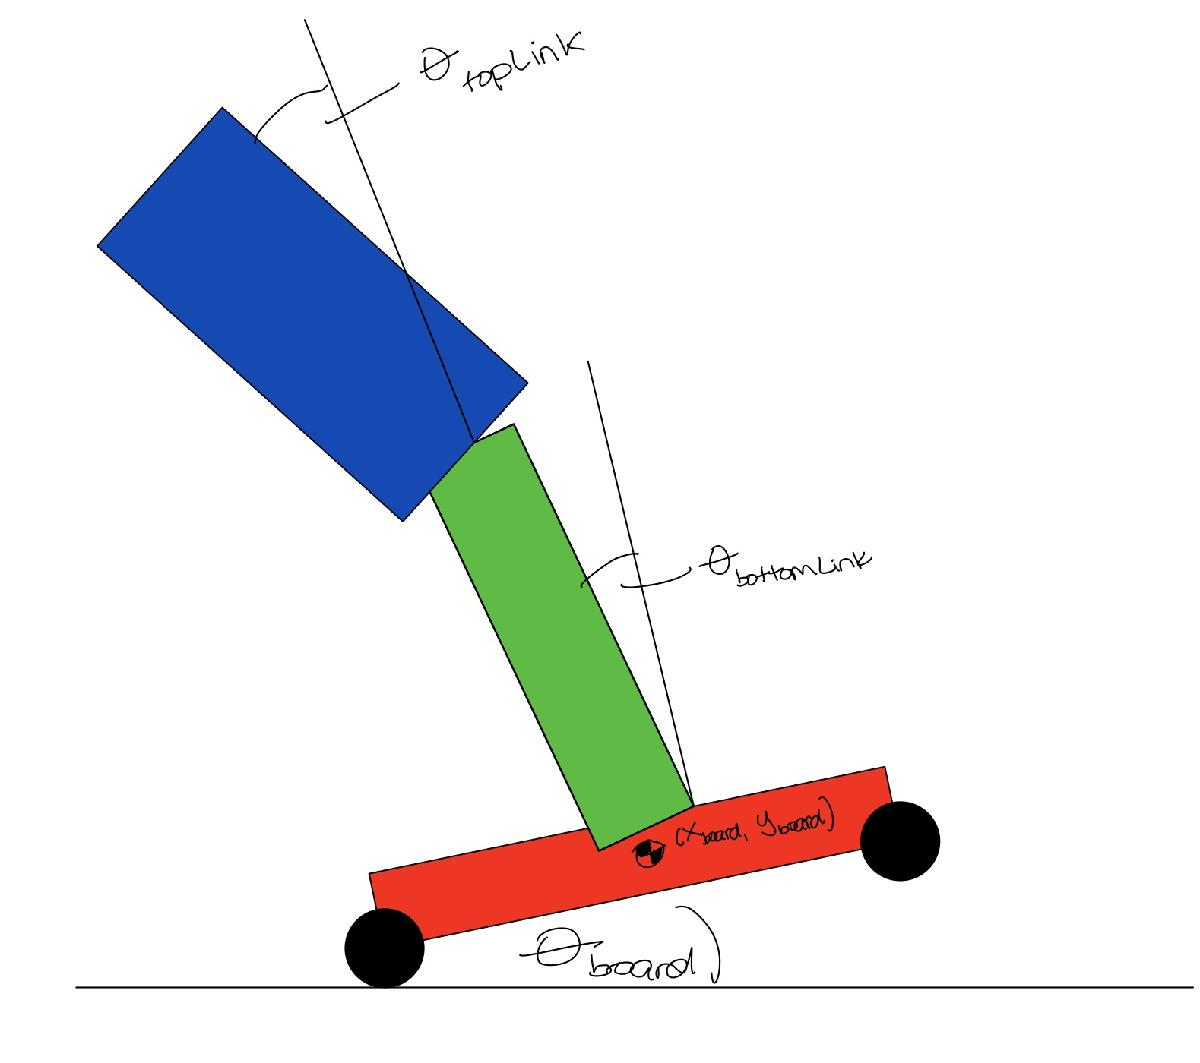

fprintf('\tInitializing generalized coordinates, velocities, accelerations, and forces...\n');

	Initializing generalized coordinates, velocities, accelerations, and forces...



% Generalized coordinates:
% boardX: position of the skateboard CoM along the x-axis
% boardY: position of the skateboard CoM along the y-axis
% boardTheta: angle of the skateboard CoM wrt the x-axis
% bottomLinkTheta: angle of the bottom link, ccw+ w.r.t. skateboard angle
% topLinkTheta: angle of the pendulum, ccw+ w.r.t. top link angle

syms boardX boardY boardTheta bottomLinkTheta topLinkTheta real
q = [boardX; boardY; boardTheta; bottomLinkTheta; topLinkTheta];

% Generalized velocities:
% boardDX: velocity of the skateboard CoM along the x-axis
% boardDY: velocity of the skateboard CoM along the y-axis
% boardDTheta: rate of change of angle of the skateboard CoM wrt the x-axis
% bottomLinkDTheta: angular velocity of angle of the bottom link, ccw+ w.r.t. skateboard angle
% topLinkDTheta: angular velocity of angle of the pendulum, ccw+ w.r.t. top link angle
syms boardDX boardDY boardDTheta bottomLinkDTheta topLinkDTheta real
dq = [boardDX; boardDY; boardDTheta; bottomLinkDTheta; topLinkDTheta];

% Generalized accelerations:
syms boardDDX boardDDY boardDDTheta bottomLinkDDTheta topLinkDDTheta real
% boardDX: acceleration of the skateboard CoM along the x-axis
% boardDY: acceleration of the skateboard CoM along the y-axis
% boardDTheta: angular acceleration of angle of the skateboard CoM wrt the x-axis
% bottomLinkDTheta: angular acceleration of angle of the bottom link, ccw+ w.r.t. skateboard angle
% topLinkDTheta: angular acceleration of angle of the pendulum, ccw+ w.r.t. top link angle
ddq = [boardDDX; boardDDY; boardDDTheta; bottomLinkDDTheta; topLinkDDTheta];

% Generalized forces:

syms  bottomMotorTorque topMotorTorque  real 
% bottomMotorTorque: torque acting on bottomLinkTheta
% topLinkTorque: torque acting on toplinkTheta

Q = [0; 0; 0; bottomMotorTorque; topMotorTorque];


fprintf('\t...done.\n');

	...done.


## Define kinematics variables

fprintf('\tInitializing kinematics variables...\n');

	Initializing kinematics variables...



% coordinates of the bottom link CoM:
syms bottomLinkXCoM bottomLinkYCoM  real
% Note: we already defined x_cart as the x-coordinate of the cart CoM.

% coordinates of the top link CoM:
syms topLinkXCoM topLinkYCoM  real

% dimensions: distance from bottom edge to CoM of the bottom and links:
syms bottomLinkRCoM topLinkRCoM real

% Dimensions: length of the bottom and top links:
syms bottomLinkHeight topLinkHeight real

% Coordinates of the overall center of mass of the robot
syms robotXCoM robotYCoM real

% Geometry of the skateboard
syms boardLength boardHeight wheelRadius real


fprintf('\t...done.\n');

	...done.


## Define inertial (and other) parameters

fprintf('\tInitializing inertial (and other) parameters...\n');

	Initializing inertial (and other) parameters...



% Mass of each body:
syms boardMass bottomLinkMass topLinkMass real

% Rotational inertia of the pendulum:
syms boardI bottomLinkI topLinkI real


% Other variables
g = sym('g','real'); % gravity
t = sym('t','real'); % time

fprintf('\t...done.\n');

	...done.


## Forward kinematics

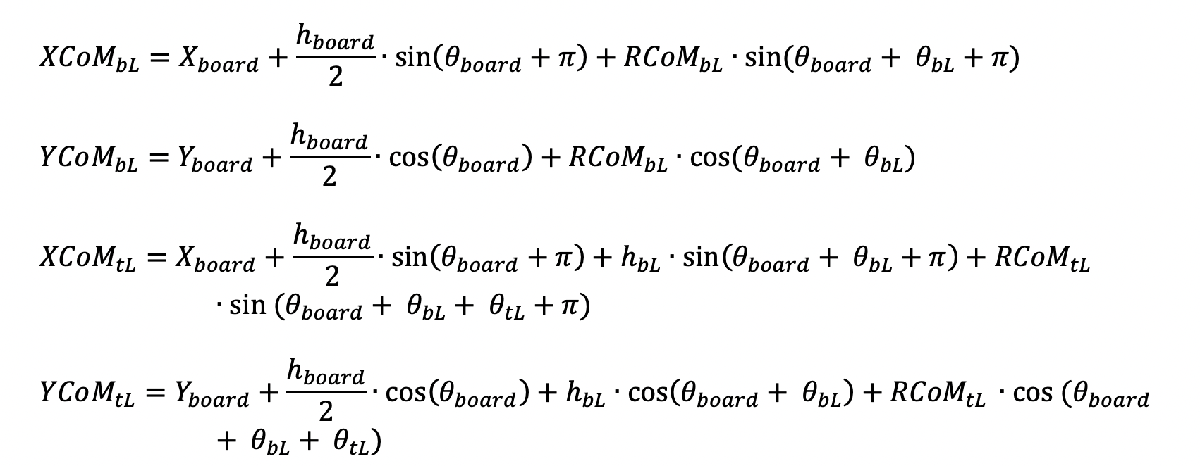


fprintf('\tGenerating forward kinematics equations...\n');

	Generating forward kinematics equations...



% Take the Y coordinate of the board considering the wheel's radius and
% height of the board, such that an input of y = 0 will place the wheels on
% the ground 

boardY = (boardY + wheelRadius + boardHeight/2);

% Compute coordinates for the CoM of the bottom link:

bottomLinkXCoM = boardX + boardHeight/2 * sin(boardTheta + pi) + bottomLinkRCoM * sin(boardTheta + bottomLinkTheta + pi);
bottomLinkYCoM = boardY + boardHeight/2 * cos(boardTheta) + bottomLinkRCoM * cos(boardTheta + bottomLinkTheta);

% Compute coordinates for the CoM of the top link:

topLinkXCoM = boardX + boardHeight/2 * sin(boardTheta + pi) + bottomLinkHeight * sin(boardTheta + bottomLinkTheta + pi) + topLinkRCoM * sin(boardTheta + bottomLinkTheta + topLinkTheta + pi); 
topLinkYCoM = boardY + boardHeight/2 * cos(boardTheta) + bottomLinkHeight * cos(boardTheta + bottomLinkTheta) + topLinkRCoM * cos(boardTheta + bottomLinkTheta + topLinkTheta);


The equation to calculate the center of mass of the robot as a whole, was calculated by taking the x- and y- coordinates of each of the parts of the robot, and multiplying it times the mass of the element, then divide it by the mass of all of the elements, as follows:

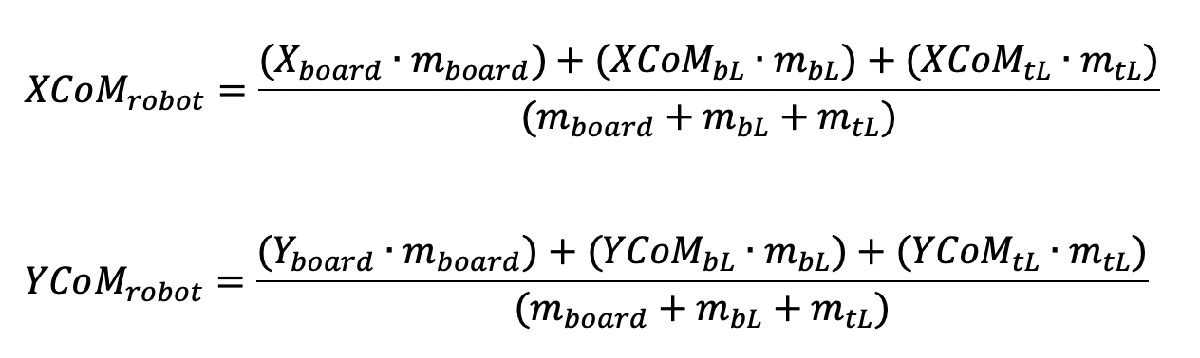


% robot's CoM

robotXCoM = (boardX * boardMass + bottomLinkXCoM * bottomLinkMass + topLinkXCoM * topLinkMass)/(boardMass + bottomLinkMass + topLinkMass);
robotYCoM = (boardY * boardMass + bottomLinkYCoM * bottomLinkMass + topLinkYCoM * topLinkMass)/(boardMass + bottomLinkMass + topLinkMass);

% compute the (x,y) location of the robot's tip:

robotTipX = boardX + boardHeight/2 * sin(boardTheta + pi) + bottomLinkHeight * sin(boardTheta + bottomLinkTheta + pi) + topLinkHeight * sin(boardTheta + bottomLinkTheta + topLinkTheta + pi); 
robotTipY = boardY + boardHeight/2 * cos(boardTheta) + bottomLinkHeight * cos(boardTheta + bottomLinkTheta) + topLinkHeight * cos(boardTheta + bottomLinkTheta + topLinkTheta);

% create a 2x5 array to hold all forward kinematics (FK) outputs:
FK = [boardX, bottomLinkXCoM, topLinkXCoM, robotXCoM, robotTipX;
      boardY, bottomLinkYCoM, topLinkYCoM, robotYCoM, robotTipY];

% generate a MATLAB function to compute all the FK outputs:
matlabFunction(FK,'File','autogen_fwd_kin');
% Note: this autogenerated function will make plotting/animation easier
% later. Could also help with some control tasks.
fprintf('\t...done.\n');

	...done.


## Constraint equations

In this case, we have set out to compute constraint equations for both of our stages: flat ground, and a ramp with a radius of 2 feet. First, we calculated the location of the left and right wheels where the constraints will have an effect, with respect to various states in *q*.

For the flat surface, the constraints will be unilateral in the Y direction, whereas in the ramp, the constraints will be unilateral in the direction normal to the ramp. Therefore, we needed to include two constraint equations and keep track of the stage that we are at through the use of two different autogenerated functions that will be called accordingly depending on the stage that we are on.

Case 1: flat

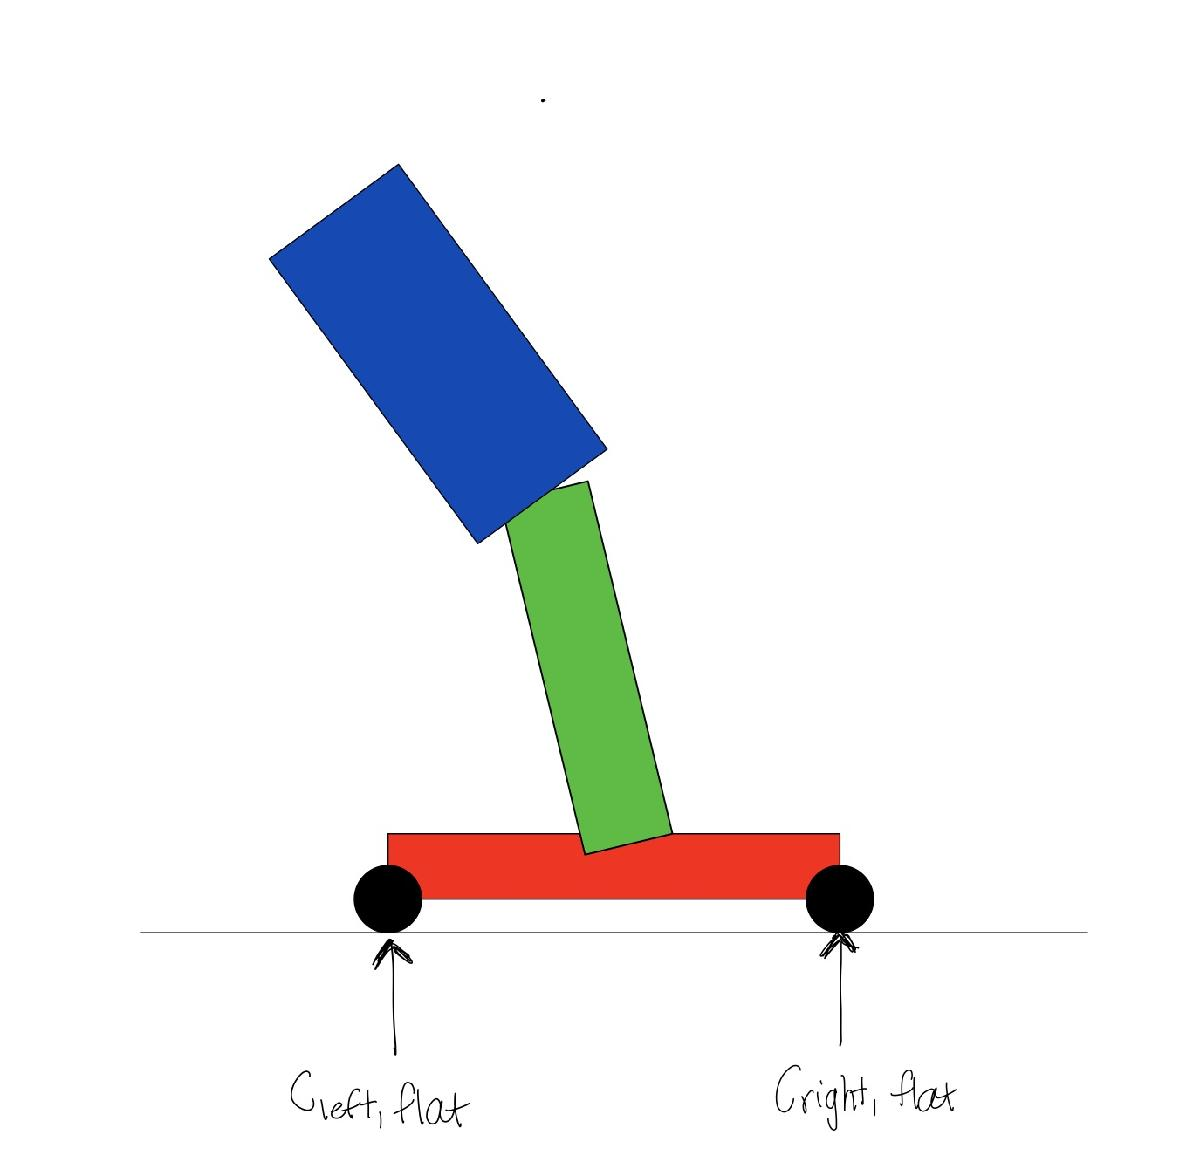

Case 2: ramp

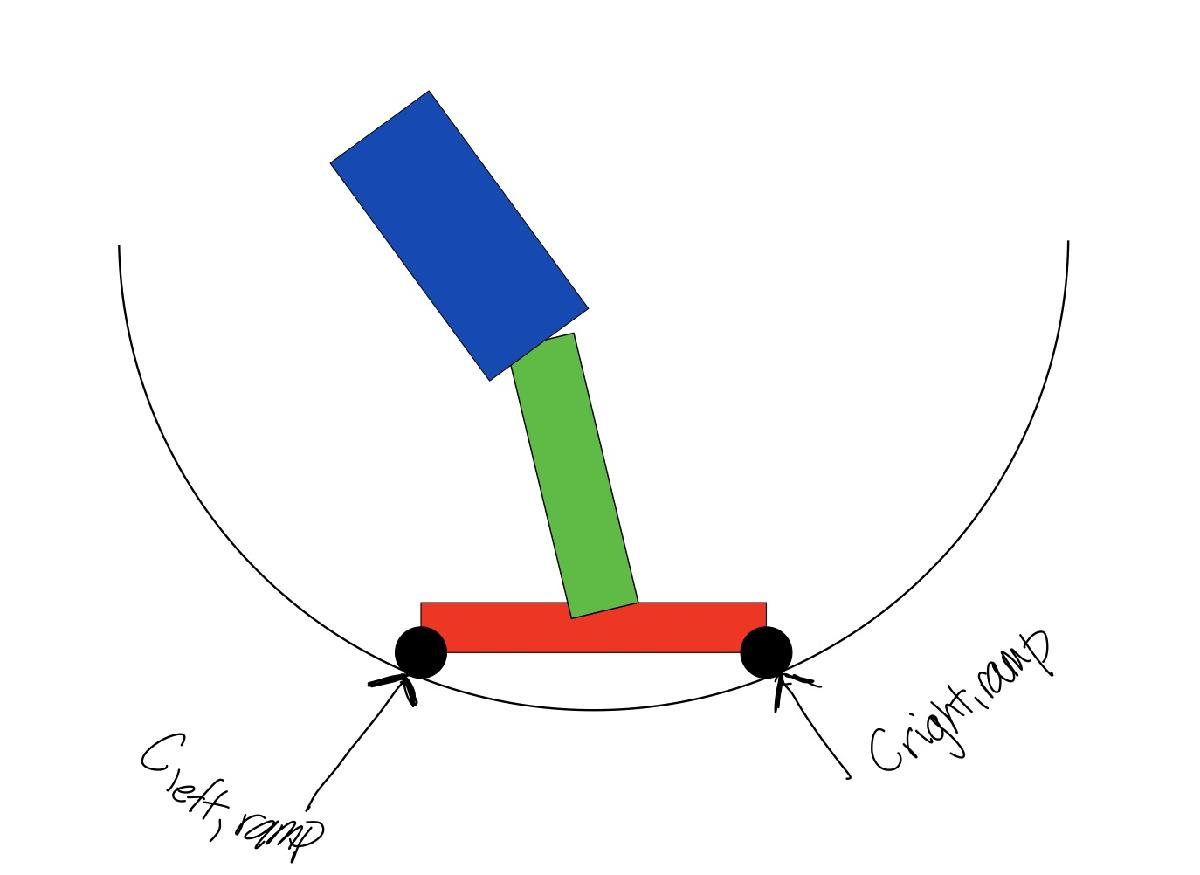

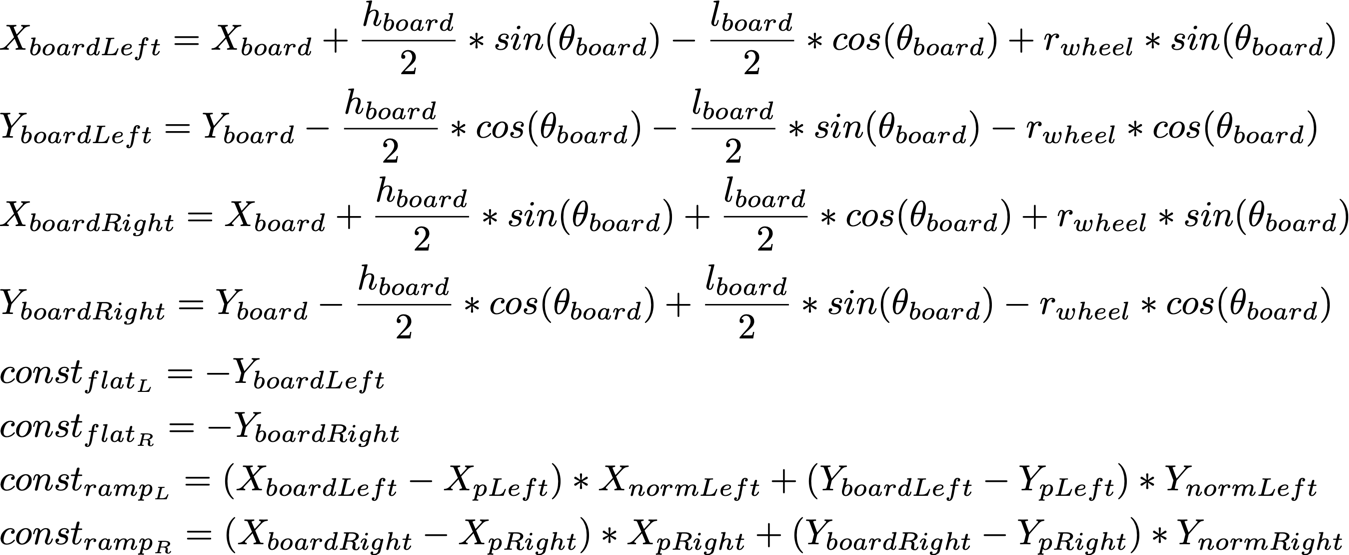

fprintf("Initializing constraint variables...\n");

Initializing constraint variables...



syms boardLeftX boardLeftY boardRightX boardRightY real
syms pLeftX pLeftY pRightX pRightY normLeftX normLeftY normRightX normRightY real
syms constL_ramp constR_ramp constL_flat constR_flat constL_ramp_lip constR_ramp_lip real

boardLeftX =  boardX + boardHeight/2 * sin(boardTheta) - boardLength/2 * cos(boardTheta) + wheelRadius * sin(boardTheta);

boardLeftY = boardY - boardHeight/2 * cos(boardTheta)  - boardLength/2 * sin(boardTheta) - wheelRadius * cos(boardTheta);

boardRightX = boardX + boardHeight/2 * sin(boardTheta) + boardLength/2 * cos(boardTheta) + wheelRadius * sin(boardTheta) ;

boardRightY = boardY - boardHeight/2 * cos(boardTheta) + boardLength/2 * sin(boardTheta) - wheelRadius * cos(boardTheta);


FK_leftWheel = [boardLeftX;boardLeftY];
FK_rightWheel = [boardRightX;boardRightY];

constL_flat = -boardLeftY;
constR_flat = -boardRightY;

constL_ramp_lip = constL_flat + 2;
constR_ramp_lip = constR_flat + 2;


constL_ramp = (boardLeftX - pLeftX)*normLeftX + (boardLeftY - pLeftY)*normLeftY;
constR_ramp = (boardRightX - pRightX)*normRightX + (boardRightY - pRightY)*normRightY;


constraints_flat = [constL_flat; constR_flat];
constraints_ramp = [constL_ramp; constR_ramp];
constraints_ramp_lip = [constL_ramp_lip; constR_ramp_lip];



matlabFunction(FK_leftWheel,FK_rightWheel,'File','autogen_fk_wheels');
matlabFunction(constraints_flat,'File','autogen_constraints_flat');
matlabFunction(constraints_ramp,'File','autogen_constraints_ramp');
matlabFunction(constraints_ramp_lip,'File','autogen_constraints_ramp_lip');


## Derivatives

fprintf('\tGenerating time derivatives of the kinematics equations...\n');

	Generating time derivatives of the kinematics equations...


% Neat trick to compute derivatives using the chain rule
% from https://github.com/MatthewPeterKelly/OptimTraj/blob/master/demo/fiveLinkBiped/Derive_Equations.m
derivative = @(in)( jacobian(in,[q;dq])*[dq;ddq] );

% CoM velocities:
syms boardDXCoM boardDYCoM bottomLinkDXCoM bottomLinkDYCoM topLinkDXCoM topLinkDYCoM real
syms leftWheelDFK rightWheelDFK real

boardDX = derivative(boardX); 
boardDY = derivative(boardY);

bottomLinkDXCoM = derivative(bottomLinkXCoM);
bottomLinkDYCoM = derivative(bottomLinkYCoM);


topLinkDXCoM = derivative(topLinkXCoM);
topLinkDYCoM = derivative(topLinkYCoM);


boardDTheta = derivative(boardTheta);
bottomLinkDTheta = derivative(bottomLinkTheta);
topLinkDTheta = derivative(topLinkTheta);


leftWheelDFK = jacobian(FK_leftWheel,q)*dq;
rightWheelDFK = jacobian(FK_rightWheel,q)*dq;

% Once again, due to the difference in constraints, there must be a
% separate A matrix and separate Hessians for the flat and the ramp stages,
% so we have a separate function for each


syms A_all_ramp H_constL_ramp H_constR_ramp real
syms A_all_flat H_constL_flat H_constR_flat real
syms A_all_ramp_lip H_constL_ramp_lip H_constR_ramp_lip real


A_all_ramp = jacobian(constraints_ramp, q);
A_all_flat = jacobian(constraints_flat, q);
A_all_ramp_lip = jacobian(constraints_ramp_lip, q);

H_constL_ramp = hessian(constL_ramp, q);
H_constR_ramp = hessian(constR_ramp, q);

H_constL_ramp_lip = hessian(constL_ramp_lip, q);
H_constR_ramp_lip = hessian(constR_ramp_lip, q);

H_constL_flat = hessian(constL_flat, q);
H_constR_flat = hessian(constR_flat, q);


matlabFunction(leftWheelDFK,rightWheelDFK,'File','autogen_wheel_velocities');
matlabFunction(bottomLinkDXCoM, bottomLinkDYCoM, topLinkDXCoM, topLinkDYCoM, 'File', 'autogen_com_velocities');
matlabFunction(A_all_ramp, H_constL_ramp, H_constR_ramp, 'File', 'autogen_constraint_derivatives_ramp');
matlabFunction(A_all_flat, H_constL_flat, H_constR_flat, 'File', 'autogen_constraint_derivatives_flat');
matlabFunction(A_all_ramp_lip, H_constL_ramp_lip, H_constR_ramp_lip, 'File', 'autogen_constraint_derivatives_ramp_lip');


fprintf('\t...done with constraint equations.\n');

	...done with constraint equations.


## Kinetic energy

We are allowing for rotation and translation of the three bodies: the skateboard, the bottom link the the top link

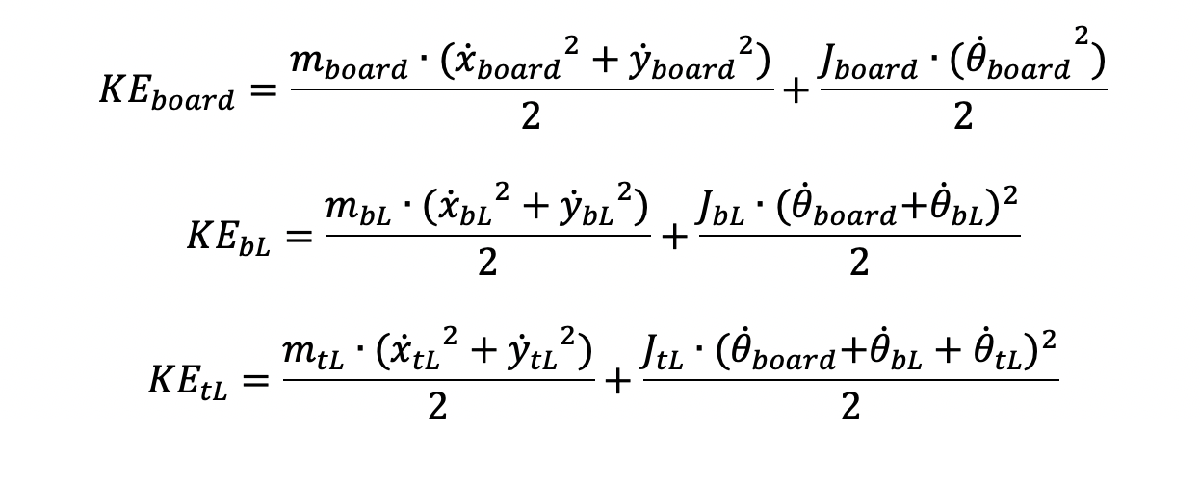

fprintf('\tGenerating kinetic energy equation...\n');

	Generating kinetic energy equation...



syms boardKE bottomLinkKE topLinkKE KE real

% kinetic energy of each body:
boardKE = 1/2 * boardMass * (boardDX^2+boardDY^2) + (1/2 * boardI * boardDTheta^2);
bottomLinkKE = (1/2* bottomLinkMass * ((bottomLinkDXCoM)^2+(bottomLinkDYCoM)^2)) + (1/2 * bottomLinkI * (boardDTheta + bottomLinkDTheta)^2);
topLinkKE = (1/2* topLinkMass * ((topLinkDXCoM)^2+(topLinkDYCoM)^2)) + (1/2 * topLinkI * (boardDTheta + bottomLinkDTheta + topLinkDTheta)^2);

% total kinetic energy:
KE = boardKE + bottomLinkKE + topLinkKE;

fprintf('\t...done.\n');

	...done.


## Potential energy

In this case, because we can consider all of the mass to be concentrated at the center of mass of the robot (which we have been keeping track of), we can just take use the CoM of the robot as the only source of gravitational potential energy.

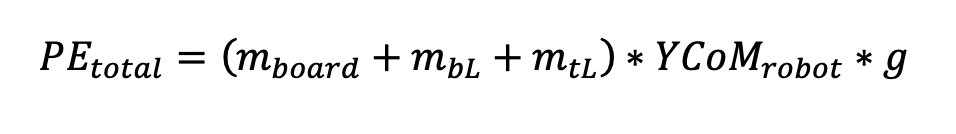

fprintf('\tGenerating potential energy equation...\n');

	Generating potential energy equation...



syms boardPE bottomLinkPE topLinkPE PE real

% potential energy of the pendulum:


PE = robotYCoM * g * (boardMass + bottomLinkMass + topLinkMass);

fprintf('\t...done.\n');

	...done.



syms totEnergy real

totEnergy = PE + KE;
matlabFunction(totEnergy,'File','autogen_total_energy');

## Lagrangian

fprintf('\tGenerating Lagrangian...\n');

	Generating Lagrangian...



syms L real
L = KE - PE;

fprintf('\t...done.\n');

	...done.


## Euler-Lagrange equations

fprintf('\tGenerating Euler-Lagrange equations of motion...\n')

	Generating Euler-Lagrange equations of motion...



% Note: the Euler-Lagrange equations of motion are
%   d(del L/del dq)/dt - (del L/del qa) = generalized forces;
% I did not include damping in my Lagrangian (although it can be done, at
% least for viscous damping) so I have to lump it in with the other
% generalized forces (in this case, the only other generalized force is the
% control input u, i.e. the force applied horizontally to the cart).


% Variable initializations:


del_L_del_dq = sym('del_L_del_dq',[numel(q),1],'real'); % del L/del q_dot
ELeq_term1  = sym('ELeq_term1',[numel(q),1],'real'); % d(del L/del dq)/dt
ELeq_term2  = sym('ELeq_term2',[numel(q),1],'real'); % del L/del q

del_L_del_dq = jacobian(KE,dq)';
ELeq_term1 = simplify(jacobian(del_L_del_dq,[q;dq])*[dq;ddq]);
ELeq_term2 = simplify(jacobian((L),q))';
% Note: no constraint forces yet

fprintf('\t...done.\n')

	...done.


fprintf('\tSolving for the mass matrix...\n');

	Solving for the mass matrix...



M = sym('M',[numel(q),numel(q)],'real');
H = sym('H',[numel(q),1],'real');

M = simplify(jacobian(del_L_del_dq,dq));
H = simplify(jacobian(del_L_del_dq,q)*dq - ELeq_term2);
G_q = simplify(jacobian(PE,q));

fprintf('\t\t...done building M and H.\n');

		...done building M and H.




% compute and store inv(M):
fprintf('\t\tComputing inv(M)...\n')

		Computing inv(M)...


Minv = sym('Minv',[numel(q),numel(q)],'real');
Minv = simplify(inv(M));
fprintf('\t\t...done.\n')

		...done.



fprintf('\t\tGenerating MATLAB functions...\n');

		Generating MATLAB functions...


matlabFunction(M,'File','autogen_mass_matrix');
fprintf('\t\t...done building M function\n');

		...done building M function


matlabFunction(Minv,'File','autogen_inverse_mass_matrix');
fprintf('\t\t...done building Minv function\n');

		...done building Minv function


matlabFunction(H,'File','autogen_h_eom');
fprintf('\t\t...done.\n');

		...done.


matlabFunction(G_q,'File','autogen_conservative_forces');
fprintf('\t\t...done.\n');

		...done.



G_jac = simplify(jacobian(G_q,q));
matlabFunction(G_jac,'File','autogen_derivative_conservative_forces');


fprintf('...done deriving cart-pendulum equations.\n');

...done deriving cart-pendulum equations.
